# Demonstration of Live Controls, Live Tasks, and Apps in MATLAB

% The true signal is a sine wave. We'll add adjustable noise.

x = linspace(0, 4*pi, 200)';
noiseLevel = 1 

noiseLevel = 1

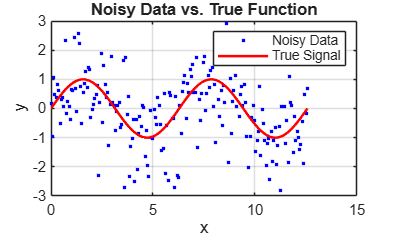

y = sin(x) + noiseLevel*randn(size(x));

figure
plot(x, y, 'b.', 'DisplayName', 'Noisy Data')
hold on
plot(x, sin(x), 'r', 'LineWidth', 1.5, 'DisplayName', 'True Signal')
legend('show')
xlabel('x')
ylabel('y')
title('Noisy Data vs. True Function')
grid on

## Live Task: Smooth Data

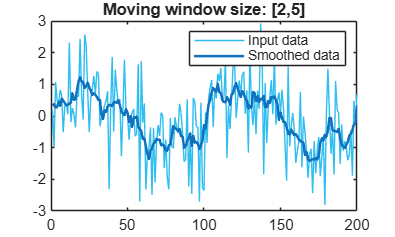

% Smooth input data
[smoothedData,winSize] = smoothdata(y,"movmean",[2 5]);

% Display results
figure
plot(y,SeriesIndex=6,DisplayName="Input data")
hold on
plot(smoothedData,SeriesIndex=1,LineWidth=1.5,DisplayName="Smoothed data")
hold off
title("Moving window size: [" + string(winSize(1)) + "," + string(winSize(2)) + "]");
legend

clear winSize

## Compare Smoothed Data

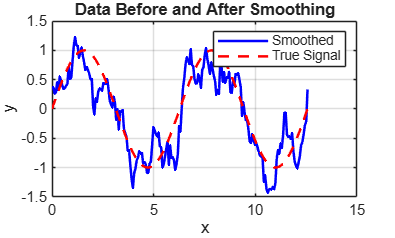

figure

plot(x, smoothedData, 'b', 'LineWidth', 1.5, 'DisplayName', 'Smoothed')
hold on
plot(x, sin(x), 'r--', 'LineWidth', 1.5, 'DisplayName', 'True Signal')
legend('show')
title('Data Before and After Smoothing')
xlabel('x')
ylabel('y')
grid on

## Launch Curve Fitting App

cftool(x, y)